Consider the confound of scanner model.

scanner: similarity of scanner model between sites

BD


                     scanner
                     _______

    spearman corr    0.23513
    p                 0.0606



SCA


SCZ


                      scanner  
                     __________

    spearman corr    -0.0072951
    p                   0.47492



ASD


MDD


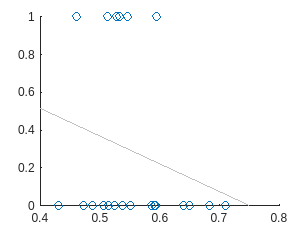

AD


                     scanner 
                     ________

    spearman corr    -0.17408
    p                 0.33892



% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag for applying COMBAT harmonization
smoothKernel = 10; % Smoothing kernel size
iter = 5000; % Number of iterations for Mantel test
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata (scanner information)
metadata = readtable(['/home/trangc/kg98/trangc/VBM/data/scanner_site_detailed.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag',  'siteList');

% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to scanner model similarity between sites
    [varTable{iDiag}, modelSim{iDiag}, nSite{iDiag}] = cor_var_scannermodel(metadata, diagnosisString(iDiag), corDiag{iDiag}, siteList{iDiag},iter, type);
    
    % Display results for the current diagnosis
    disp(char(diagnosisString(iDiag))); % Display diagnosis name
    disp(varTable{iDiag}); % Display variance table
end


% Suppress warnings related to the last operation
warning('off', 'last');

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.


% Save results to a .mat file
save('output/confound_scannerModel.mat', 'varTable', 'modelSim','nSite');
